clear
R1_uz=100; % Ом
R2_uz=3; % Ом
C_uz=200; % мкФ
U_uz=60; % В

syms u_L L t i(t) R R_k C L i_L0 U
eq1=L*diff(i)+R*i-U

$$eq1(t) = L\,\frac{\partial }{\partial t}i\left(t\right)-U+R\,i\left(t\right)$$

cond=i(0)==0

$$cond = i\left(0\right)=0$$

i_L=dsolve(eq1,cond)

$$i\_L = \frac{U-U\,{\mathrm{e}}^{-\frac{R\,t}{L}}}{R}$$

syms R C t u(t) U
eq2=R*C*diff(u)+u-U

$$eq2(t) = C\,R\,\frac{\partial }{\partial t}u\left(t\right)-U+u\left(t\right)$$

cond=u(0)==0

$$cond = u\left(0\right)=0$$

u_C=dsolve(eq2,cond)

$$u\_C = U-U\,{\mathrm{e}}^{-\frac{t}{C\,R}}$$

syms i_C t u_C(t) R2
eq3=C*diff(u_C)-i_C

$$eq3(t) = C\,\frac{\partial }{\partial t}u_{C}\left(t\right)-i_{C}$$

% R2*i_C+u_C=0 => i_C=-u_C/R2
eq3=C*diff(u_C)+u_C/R2

$$eq3(t) = C\,\frac{\partial }{\partial t}u_{C}\left(t\right)+\frac{u_{C}\left(t\right)}{R_{2}}$$

cond=u_C(0)==U

$$cond = u_{C}\left(0\right)=U$$

u_C=dsolve(eq3,cond)

$$u\_C = U\,{\mathrm{e}}^{-\frac{t}{C\,R_{2}}}$$

i_C=-u_C/R2

$$i\_C = -\frac{U\,{\mathrm{e}}^{-\frac{t}{C\,R_{2}}}}{R_{2}}$$

u_C1=subs(u_C,[U C R2],[U_uz C_uz*1e-6 R2_uz])

$$u\_C1 = 60\,{\mathrm{e}}^{-\frac{5000\,t}{3}}$$

i_C1=subs(i_C,[U C R2],[U_uz C_uz*1e-6 R2_uz])

$$i\_C1 = -20\,{\mathrm{e}}^{-\frac{5000\,t}{3}}$$

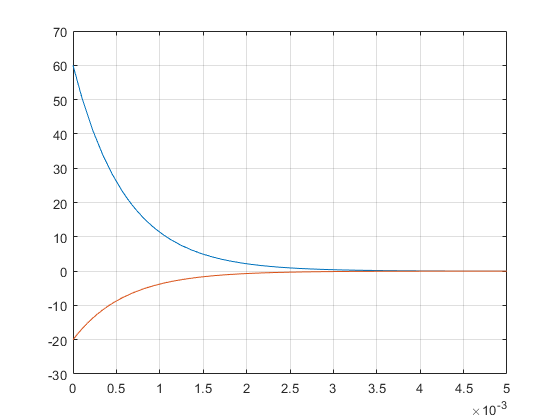

fplot(u_C1)
hold on
fplot(i_C1)
xlim([0 5e-3])
ylim([-30 70])
grid
hold off

% Другое решение
syms A lambda R2 C
u_C=A*exp(lambda*t)

$$u\_C = A\,{\mathrm{e}}^{\lambda \,t}$$

u_C=subs(u_C,[A lambda],[U -1/(R2*C)])

$$u\_C = U\,{\mathrm{e}}^{-\frac{t}{C\,R_{2}}}$$

i_C=U/R2*exp(lambda*t)

$$i\_C = \frac{U\,{\mathrm{e}}^{\lambda \,t}}{R_{2}}$$

i_C=subs(i_C,lambda,-1/(R2*C))

$$i\_C = \frac{U\,{\mathrm{e}}^{-\frac{t}{C\,R_{2}}}}{R_{2}}$$

W=int(i_C^2*R2,t,0,inf)

$$W = \begin{array}{l} \left\{ \begin{array}{cl} \frac{U^{2}\,\left(\frac{C\,R_{2}}{2}+\left(-C\,R_{2}\right)\,\infty \right)}{R_{2}} & \text{ if }\frac{1}{C\,R_{2}}<0\\ -\frac{U^{2}\,\left(\frac{\lim_{t\to \infty }C\,R_{2}\,{\mathrm{e}}^{-\frac{2\,t}{C\,R_{2}}}}{2}-\frac{C\,R_{2}}{2}\right)}{R_{2}} & \text{ if }\neg \frac{1}{C\,R_{2}}<0\wedge \sigma_{1}<0\\ \frac{C\,U^{2}}{2} & \text{ if }0\leq \sigma_{1}\vee C=0\vee R_{2}=0\vee \text{angle}\left(\frac{1}{C\,R_{2}}\right)\in \left(-\frac{\pi }{2},\frac{\pi }{2}\right) \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\mathrm{real}\left(\frac{1}{C\,R_{2}}\right) \end{array}$$

W=C*U^2/2

$$W = \frac{C\,U^{2}}{2}$$